# Drying of non-porous solid materials

Drying is the process of removing liquids from a wet solid by heat. The liquid to be removed is usually water. By adding heat to the solid, the moisture is vaporized and took away. Therefore, drying consists in an exchange of heat and mass between a wet solid and a drying fluid. The dryier agent usually is air in forced convection. The entire process may be realized in a heater or in the environment. In the last case, water may be vaporized by natural convection (as in the case of a wet floor). For an industrial application, forced convection of heated air is used to speed-up the process.

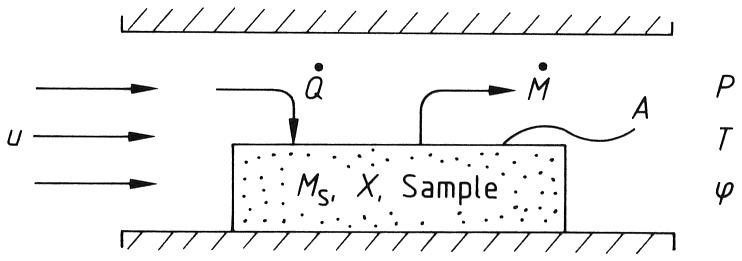

## Theory

Drying happens at a given rate, which depends on the mass of the wet solid $M_\text{s}$, the contact area $A$ between the solid and the drying agent, and the rate of removal of the moisture content ($X$: mass of liquid per unit mass of dry solid). That is, the removal of moisture per unit of time is:


$$\dot{m} = - \frac{M_\text{s}}{A} \frac{\mathrm{d}X}{\mathrm{d}t}$$


where the drying rate $\dot{m}$ has dimensions of a mass per unit area and time, usually expressed in kilogram of water per square meter per hour.

In the case of non-porous solids, only the surface liquid must be removed. In this case, the rate of change of the humid content - and consequently the drying rate - is constant:


$$\frac{\mathrm{d}X}{\mathrm{d}t} = \frac{\Delta X}{\Delta t} = \text{constant}$$


The drying on the contact surface happens at a constant drying rate. Such process is also realized in the first drying period of a porous wet solid, anyway.

The idea is to supply heat to vaporize the moisture and remove it by forced convection. The drying agent is initially at a pressure $p$, temperature $T$, and relative humidity $\varphi$ (percentage of moisture with respect to saturation value, within the range 0 to 1, where 0 indicates a completely dry gas and 1 indicates a saturated gas). Pre-heating the drying agent will not change its absolute water content $X$, but will reduce its relative humidity $\varphi$. That is, heated air with given content $X$ of vapor water per unit mass of dry air is less saturated than the same air at a lower temperature. Thus, relative humidity is a function of the temperature. The Mollier diagram is useful to understand the process.

mollier

The Mollier chart represents the (absolute) humidity $X$ on the abscissa and the gas temperature on the ordinate axis. Lines of constant specific enthalpy are drawn as dashed lines. At zero humidity, the specific enthaply in kJ/kg coincides with the temperature value in Celsius degrees. Lines of constant relative humidity $\varphi$ are also drawn. Observe that, for a given value of $X$, the relative humidity $\varphi$ reduces with increasing temperature. That is, hot air is not less humid than cold air, but can support more water vapor before getting saturated.

The heated gas is blown on the surface to be dried, vaporizing the liquid and taking it out downstream. **Assuming that all the energy will be used to vaporize the moisture**, the heat flux is equal to the product of the drying rate $\dot{m}$ and the (specific) vaporization enthaply $\Delta h_\text{v}$:


$$\dot{q} = \dot{m} \Delta h_\text{v}$$


Let $Y$ be the humidity of the drying agent and $Y^*$ its saturation value. It is assumed that on the contact surface, where liquid water is present, the gas will be saturated. That is:


$$Y_\text{s} = Y^*(T_\text{s})$$


where the saturation value depends on the temperature $T_\text{s}$ of the solid contact area. **The drying rate will be proportional to the humidity difference of the gas between the saturation and the environment conditions**. The constant of proportionality is the product of the effective mass transfer coefficient $\beta_g^0$ and the gas density $\rho_g$. In maths:


$$\dot{m} = \rho_g \, \beta_g^0 \, \left[ Y^*(T_\text{s}) - Y \right]$$


We need another equation to close the problem. The heat transfer equation relates the heat flux $\dot{q}$ to the fluid effective heat transfer coefficient and a change in temperature:


$$\dot{q} = \alpha^0 \, (T_\text{g} - T_\text{s})$$


By subtitution we get:


$$\alpha^0 \, (T_\text{g} - T_\text{s}) = \rho_g \, \beta_g^0 \, \left[ Y^*(T_\text{s}) - Y \right]$$


The unknown in the above equation is the solid temperature $T_\text{s}$ that drives the saturation humidity $Y^*$. For solids wetted by water and dried by air, it is valid the approximation:


$$\frac{\alpha^0}{\beta_g^0} \frac{1}{\rho_\text{g}} \approx c_{p_\text{g}} + Yc_{p_\text{v}}$$


where $c_{p_\text{g}}$ is the constant pressure specific heat of *dry air* and $c_{p_\text{v}}$ is the constant pressure specific heat of *water vapor*. This approximation enables the use of the Mollier diagram in finding the point of coordinates $(Y^*,T_\text{s})$, which correspond to a point of the *adiabatic saturation line* of equation:


$$\frac{h^*(T_\text{s}) - h} {Y^*(T_\text{s}) - Y} = c_{p_\text{l}} T_\text{s}$$


where $c_{p_\text{l}}$ is the constant pressure specific heat of liquid water and $h$ is the specific enthalpy of moist air:


$$h = c_{p_\text{g}} T + Y \left( \Delta h_\text{v}^0 + c_{p_\text{v}} T \right)$$


where $\Delta h_\text{v}^0$ is the vaporization enthalpy at 0°C.

**In shorts, it is assumed that the vaporization of the water on the surface of the wet solid happens with an adiabatic transformation. All the heat is used to make a phase change from liquid water to water vapour.**

## **Textbook application**

Here is a practical application taken from [1]: ambient air at 22°C and 60% relative humidity is pre-heated to 72°C and used to dry a wet solid. Calculate the rate of drying, knowing the heat transfer coefficient and other gas constants.

close all; clearvars; clc

% Input data
p_amb = 101325; % ambient pressure in Pascal
T_amb = 22;     % temperature in Celsius of ambient air
phi_amb = 0.6;  % relative humidity (0.05 - 1.00) of ambient air
T_prh = 72;     % temperature in Celsius of preheated air

We need some preliminary calculations: the water vapour pressure is used to calculate the air humidity that, together with specific heat constants and vaporization enthalpy, will be used to calculate the enthalpy of pre-heated air.

The vapour pressure of air is calculated with an anonymous function and the values at ambient temperature and pre-heated temperature are stored:

% Water vapor pressure in Pascal
vaporPressure = @(T) 0.61121 * exp((18.678 - T/234.5) .* T./(257.14 + T)) * 1000;
pv_amb = vaporPressure(T_amb) % water vapor pressure of ambient air

pv_amb = 2.6442e+03

pv_prh = vaporPressure(T_prh) % water vapor pressure of preheated air

pv_prh = 3.4000e+04

The source of the above equation is Ref. [2].

The humidity of air $Y$ depends on the ratio of molecular masses between water vapour and dry air as well as its vapour pressure and ambient pressure. This value is used to calculate the relative humidity of pre-heated air (remember that heat does not change the absolute value of humidity, only the relative value with respect to the saturation):

% Air humidity in kg water per kg dry air
Y = 18.01/28.96 * phi_amb * pv_amb ./ (p_amb - phi_amb * pv_amb)

Y = 0.0099


% Relative humidity of preheated air
phi_prh = p_amb / pv_prh * Y / (18.01/28.96 + Y)

phi_prh = 0.0467

These data, together with air and water constants, are used to calculate the enthalpy $h$ of the pre-heated air:

% Air and water vapor constants
Cpg = 1000; % air specific heat at constant pressure in J / (kg K)
Cpv = 1860; % water vapor specific heat at constant pressure in J / (kg K)
Cpl = 4200; % liquid water specific heat at constant pressure in J / (kg K)
delta_hv_0 = 2500900; % water vaporization enthalpy at 0°C in J/kg

% Enthalpy of preheated air in J/kg
h = Cpg * T_prh + Y * (delta_hv_0 + Cpv*T_prh)

h = 9.8065e+04

Additional anonymous functions are introduced to evaluate the humidity and specific enthalpy of air in contact with the solid. The first two are simply the two above equations written for a saturated gas ($\varphi = 1.0$). The third is the equation of the adiabatic saturation line cited in the theory. In other words, the coordinates of the point $(Y^*,T_\text{s})$ on the Mollier diagram for saturated air in contact with the solid are calculated:

% Saturation coordinates
Y_star_fun = @(T) 18.01/28.96 * vaporPressure(T) ./ (p_amb - vaporPressure(T));
h_star_fun = @(T) Cpg * T + Y_star_fun(T) * (delta_hv_0 + Cpv*T);
adb_line_fun = @(T) (h_star_fun(T) - h) / (Y_star_fun(T) - Y) - Cpl*T;

T_star = fzero(adb_line_fun,T_prh)

T_star = 30.1448

Y_star = Y_star_fun(T_star)

Y_star = 0.0274

h_star = h_star_fun(T_star)

h_star = 1.0029e+05

Finally, the drying rate is estimated:

% Drying rate
alpha = 20; % heat transfer coefficient in W / (m2 K)
delta_hv = 2430300; % vaporization enthalpy at T* in J/kg
Mdot = alpha * (T_prh - T_star) / delta_hv * 3600  % drying rate in kg / (m2 h)

Mdot = 1.2400

Check the result with Ref. [1]. The entire process can be visualized on the Mollier diagram:

%% Plot of the Mollier diagram
temp = [-20, 80];
mollier([phi_amb, phi_prh, 1.0], [40, 80, 120]*1000, temp, p_amb)

% Add annotations
hold on
ax = plot([Y, Y]*1000, [temp(1), T_amb], 'k--');
label(ax,'Y', 'location','left')

ax = plot([Y_star, Y_star]*1000, [temp(1), T_star], 'k--');
label(ax,'Y^*', 'location','left')

ax = plot([0, Y]*1000, [T_amb, T_amb], 'k');
label(ax,'T_{amb}', 'location','top')

ax = plot([0, Y]*1000, [T_prh, T_prh], 'k');
label(ax,'T_{preheat}', 'location','top')

ax = plot([Y, Y_star]*1000, [T_prh, T_star], 'k', 'LineWidth',0.1);
label(ax,'adiabatic saturation line', 'location','left','slope')

ax = plot([0, Y_star]*1000, [T_star, T_star], 'k');
label(ax,'T^*', 'location','top')

quiver(0,T_amb,Y*1000,0,'off','LineWidth',2)
quiver(Y*1000,T_amb,0,T_prh-T_amb,'off','LineWidth',2)
quiver(Y*1000,T_prh,(Y_star-Y)*1000,T_star-T_prh,'off','LineWidth',2);
quiver(Y_star*1000,T_star,-Y_star*1000,0,'off','LineWidth',2)

hold off
xlabel('Humidity, g H_2O / kg dry air')

Observe that the adiabatic saturation line is almost parallel to a line of constant enthalpy. It cannot be parallel because the process involves a change in enthalpy.

## Interactive example

You may want to explore similar applications, perhaps drying a cylindrica sample of a given mass with a given water content, where the heat transfer coefficient is initially unknown, and with a specified air flux passing through a pipe (or nozzle) of a given section area. Also you may want to get the time of drying, in addition to the drying rate.

close all; clearvars; clc

% Input data
MwdX = 0.007 * 0.001; % mass of the sample times the water to be removed per kg of sample mass
pvol = 20;      % air flux in m3/h
Au = 0.0023;   % pipe (or nozzle outlet) section area in m2 (should be larger than the sample projected area)
D = 0.013;      % sample diameter
H = 0.1;      % sample height
p_amb = 101325; % ambient pressure in Pascal
T_amb = 24;     % temperature in Celsius of ambient air
phi_amb = 0.6;  % relative humidity (0.05 - 1.00) of ambient air
T_prh = 30;     % temperature in Celsius of preheated air

% Water vapor pressure in Pascal
vaporPressure = @(T) 0.61121 * exp((18.678 - T/234.5) .* T./(257.14 + T)) * 1000;
pv_amb = vaporPressure(T_amb) % water vapor pressure of ambient air

pv_amb = 2.9845e+03

pv_prh = vaporPressure(T_prh) % water vapor pressure of preheated air

pv_prh = 4.2451e+03


% Air humidity in kg water per kg dry air
Y = 18.01/28.96 * phi_amb * pv_amb ./ (p_amb - phi_amb * pv_amb)

Y = 0.0112


% Relative humidity of preheated air
phi_prh = p_amb / pv_prh * Y / (18.01/28.96 + Y)

phi_prh = 0.4218


% Air and water vapor constants
Cpg = 1000; % air specific heat at constant pressure in J / (kg K)
Cpv = 1860; % water vapor specific heat at constant pressure in J / (kg K)
Cpl = 4200; % liquid water specific heat at constant pressure in J / (kg K)
delta_hv_0 = 2500900; % water vaporization enthalpy at 0°C in J/kg

% Enthalpy of preheated air
h = Cpg * T_prh + Y * (delta_hv_0 + Cpv*T_prh)

h = 5.8605e+04


% Saturation coordinates
Y_star_fun = @(T) 18.01/28.96 * vaporPressure(T) ./ (p_amb - vaporPressure(T));
h_star_fun = @(T) Cpg * T + Y_star_fun(T) * (delta_hv_0 + Cpv*T);
adb_line_fun = @(T) (h_star_fun(T) - h) / (Y_star_fun(T) - Y) - Cpl*T;

T_star = fzero(adb_line_fun,T_prh)

T_star = 20.4843

Y_star = Y_star_fun(T_star)

Y_star = 0.0151

h_star = h_star_fun(T_star)

h_star = 5.8946e+04

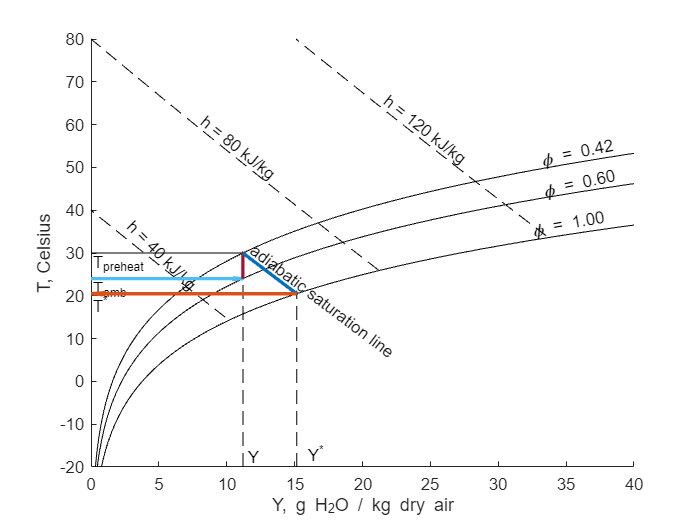


%% Plot of the Mollier diagram
temp = [-20, 80];
mollier([phi_amb, phi_prh, 1.0], [40, 80, 120]*1000, temp, p_amb)

% Add annotations
hold on
ax = plot([Y, Y]*1000, [temp(1), T_amb], 'k--');
label(ax,'Y', 'location','left')

ax = plot([Y_star, Y_star]*1000, [temp(1), T_star], 'k--');
label(ax,'Y^*', 'location','left')

ax = plot([0, Y]*1000, [T_amb, T_amb], 'k');
label(ax,'T_{amb}', 'location','top')

ax = plot([0, Y]*1000, [T_prh, T_prh], 'k');
label(ax,'T_{preheat}', 'location','top')

ax = plot([Y, Y_star]*1000, [T_prh, T_star], 'k', 'LineWidth',0.1);
label(ax,'adiabatic saturation line', 'location','left','slope')

ax = plot([0, Y_star]*1000, [T_star, T_star], 'k');
label(ax,'T^*', 'location','top')

quiver(0,T_amb,Y*1000,0,'off','LineWidth',2)
quiver(Y*1000,T_amb,0,T_prh-T_amb,'off','LineWidth',2)
quiver(Y*1000,T_prh,(Y_star-Y)*1000,T_star-T_prh,'off','LineWidth',2);
quiver(Y_star*1000,T_star,-Y_star*1000,0,'off','LineWidth',2)

hold off
xlabel('Y, g H_2O / kg dry air')
ylabel('T, Celsius')

Further details are added by including the air velocity from simple continuity considerations and the characteristic numbers (Prandtl, Reynolds, and Nusselt) of air at *film* temperature. The Nusselt number is given for a cylinder normally invested to its lateral surface (see Ref. [3] for details):

%% Drying rate calculation
flowDens = @(p,R,T) p / (R * (T + 273.15));
rho_prh = flowDens(p_amb,287,T_prh) % preheated air density, kg/m3

rho_prh = 1.1646

V = pvol/3600/Au   % air velocity in m/s

V = 2.4155


% Fluid properties
dynVisc = @(T) 1.458E-6 * (T+273.15)^1.5 / (T + 383.55) % Sutherland law for dynamic viscosity

dynVisc = function_handle with value:
    @(T)1.458E-6*(T+273.15)^1.5/(T+383.55)


thermCond = @(T) 0.0121 * exp(0.0025 * T) % air thermal conductivity

thermCond = function_handle with value:
    @(T)0.0121*exp(0.0025*T)


mug = dynVisc(0.5*(T_prh+T_star)); % air dynamic viscosity
k = thermCond(0.5*(T_prh+T_star)); % air thermal conductivity
Pr = mug * Cpg / k % Prandtl number

Pr = 1.4264

rho = flowDens(p_amb,287,0.5*(T_prh+T_star)) % preheated air density, kg/m3

rho = 1.1832

Re = rho * V * D / mug % Reynolds number

Re = 2.0209e+03

Nu = 0.3 + 0.62*Re^0.5*Pr^0.333 / (1+(0.4*Pr)^0.666)^0.25 * (1+(Re/282000)^0.625)^0.8 % Nusselt number

Nu = 28.8227

alpha = Nu * k / D

alpha = 28.5748


delta_hv = (-0.0064*T_star^2 - 1.5522*T_star + 2485) * 1000 % vaporization enthalpy at T*

delta_hv = 2.4505e+06

alpha_eff = alpha * delta_hv/(Cpv*(T_prh-T_star)) * log(1 + Cpv*(T_prh-T_star)/delta_hv) % effective heat transfer coefficient

alpha_eff = 28.4721

Mdot = alpha_eff * (T_prh - T_star) / delta_hv  % drying rate in kg/(m2 s)

Mdot = 1.1056e-04


As = pi*D/2 * H;    % sample area hit by airflow (half sample), m2
time = MwdX / (As*Mdot) % drying time in second

time = 31.0052

## References

[1] Tsotsas, E., Gnielinski, V. and Schlünder, E.-U. (2000). *Drying of Solid Materials*. In: Ullmann's Encyclopedia of Industrial Chemistry. [https://doi.org/10.1002/14356007.b02_04](https://doi.org/10.1002/14356007.b02_04)

[2] Albornoz, J. (2010).  *A Matlab code to calculate the specific enthalpy of cooled moist air*. Fujitsu Laboratories of Europe. [https://www.academia.edu/38993465/A_Matlab_code_to_calculate_the_specific_enthalpy_of_cooled_moist_air](https://www.academia.edu/38993465/A_Matlab_code_to_calculate_the_specific_enthalpy_of_cooled_moist_air) 

[3] Barhami, M. (2011). *Forced Convection Heat Transfer*. In: ENSC 388 Engineerimg Thermodynamics and Heat Transfer, Simon Fraser University. [https://www.sfu.ca/~mbahrami/ENSC%20388/Notes/Forced%20Convection.pdf](https://www.sfu.ca/~mbahrami/ENSC%20388/Notes/Forced%20Convection.pdf) 